SIG - Initiation Traitement Signal - TP1

clear all;  % efface toutes les variables déjà créées 
close all;  % ferme toutes les figures
clc;        % efface l'historique des commandes

Partie 1 : Convolution et Transformee de Fourier

Partie 1.1 - Initialisation

fe = 1024;    % Frequence d'echantillonage en Hz
D = 1;     % Durée du signal en s
dt = 1 / fe;
t = -D / 2:dt:D / 2;     % Creation de l'axe temporel
T = 25;     % Largeur de la porte en nb d'echantillons

Création du signal s

s = ones(size(t));
s(t > T / fe)=0;
s(t < -T / fe)=0;

Affichage du signal

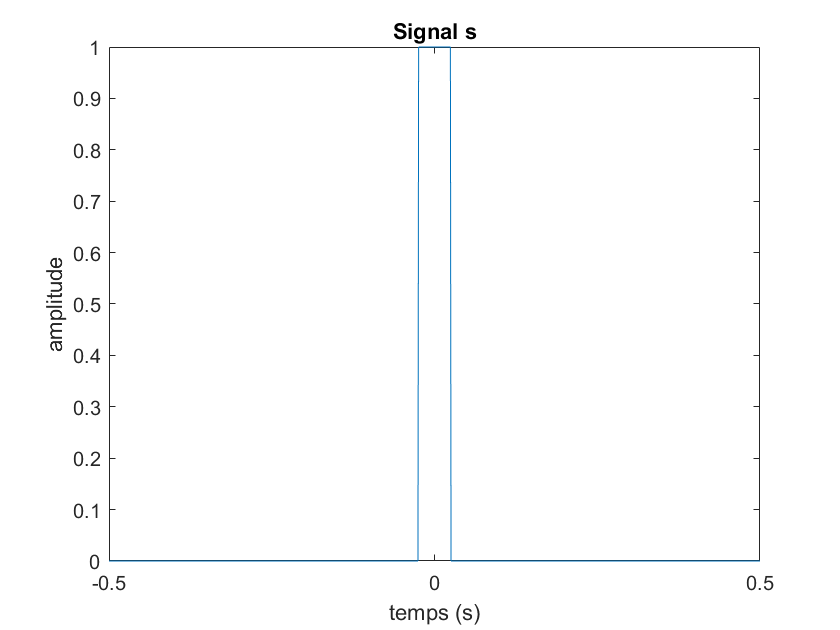

figure(1);
plot(t, s);
title('Signal s');
xlabel('temps (s)');
ylabel('amplitude');

Partie 1.2 :

f = (-fe/2 : fe / length(s) : (fe / 2 - fe / length(s))); % Creation de l'axe des frequences
S = fft(s); % TF du signal s
moduleS = abs(S);
phaseS = angle(S);

Affichage

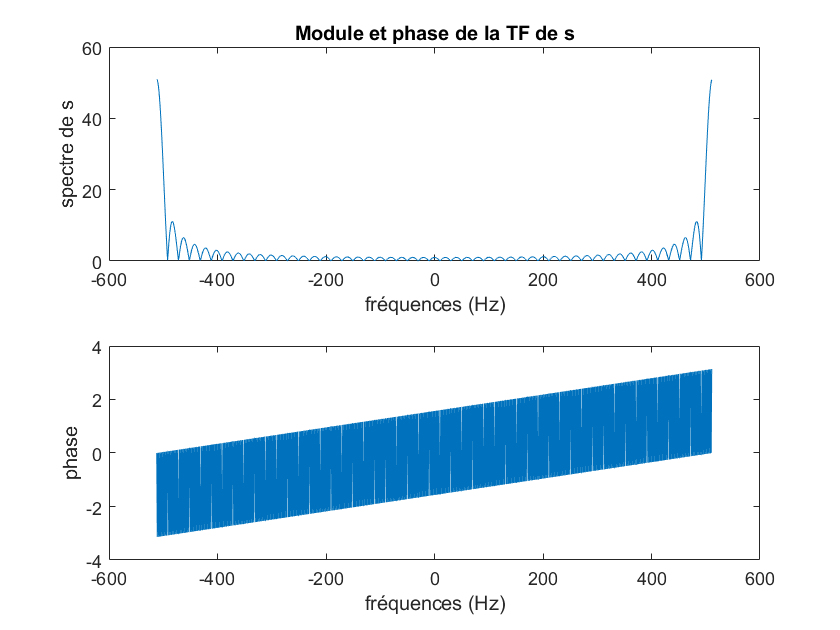

figure(2);
subplot(2, 1, 1); plot(f, moduleS);
xlabel('fréquences (Hz)');
ylabel('spectre de s');
title('Module et phase de la TF de s');
subplot(2, 1, 2); plot(f, phaseS);
xlabel('fréquences (Hz)');
ylabel('phase');

Partie 1.3

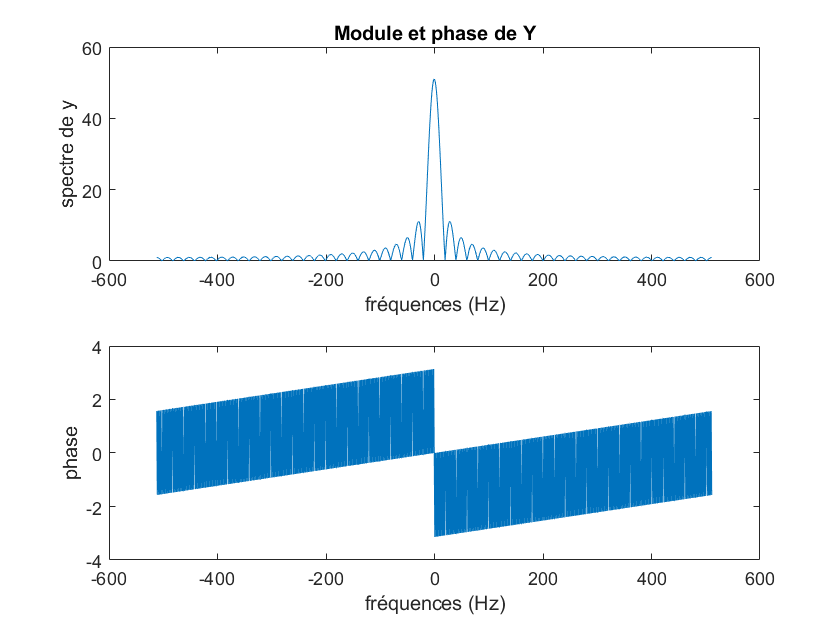

Y = fftshift(S);    % Permutation a l'aide de fftshift
moduleY = abs(Y);
phaseY = angle(Y);
figure(3);
subplot(2, 1, 1); plot(f, moduleY);
xlabel('fréquences (Hz)');
ylabel('spectre de y');
title('Module et phase de Y');
subplot(2, 1, 2); plot(f, phaseY);
xlabel('fréquences (Hz)');
ylabel('phase');

Partie 1.4

y_prime = ifft(Y);  % TF inverse de Y
s_prime = ifft(S);  % TF inverse de S

figure(4);
subplot(1, 2, 1); plot(t, y_prime);

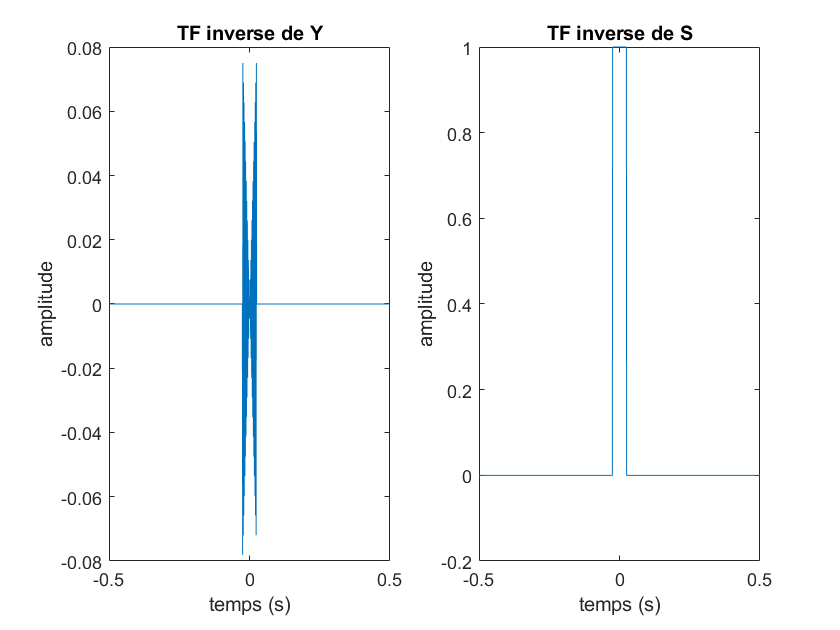

xlabel("temps (s)");
ylabel("amplitude");
title("TF inverse de Y");
subplot(1, 2, 2); plot(t, s_prime);
xlabel("temps (s)");
ylabel("amplitude");
title("TF inverse de S");

Partie 1.5

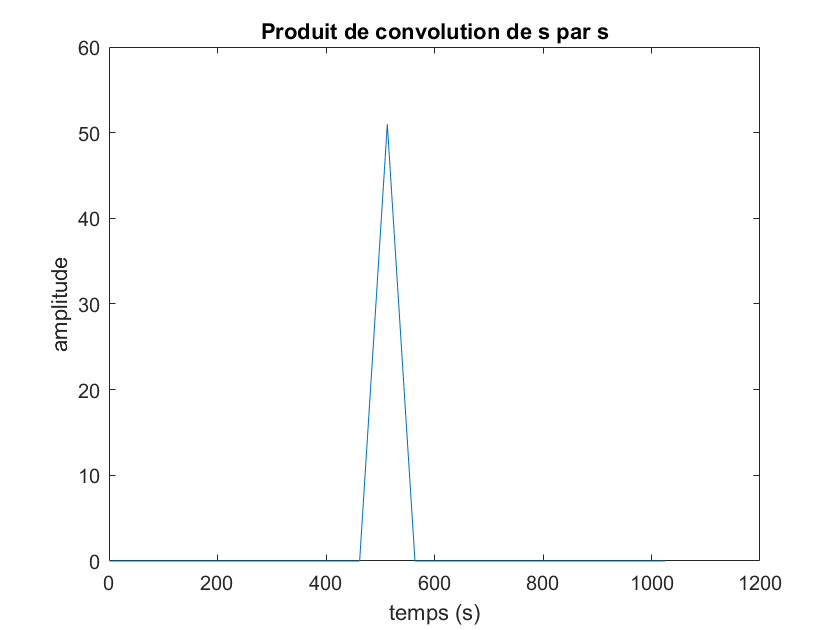

x = conv(s, s, 'same');
figure(5);
plot(x);
xlabel("temps (s)");
ylabel("amplitude");
title("Produit de convolution de s par s");

Partie 1.6

X = fft(x);         % TF de x
S_carre = S .* S;     % Elevation au carre de S
figure(6);
plot(f, abs(X)); hold on;

plot(f, abs(S), '--');   

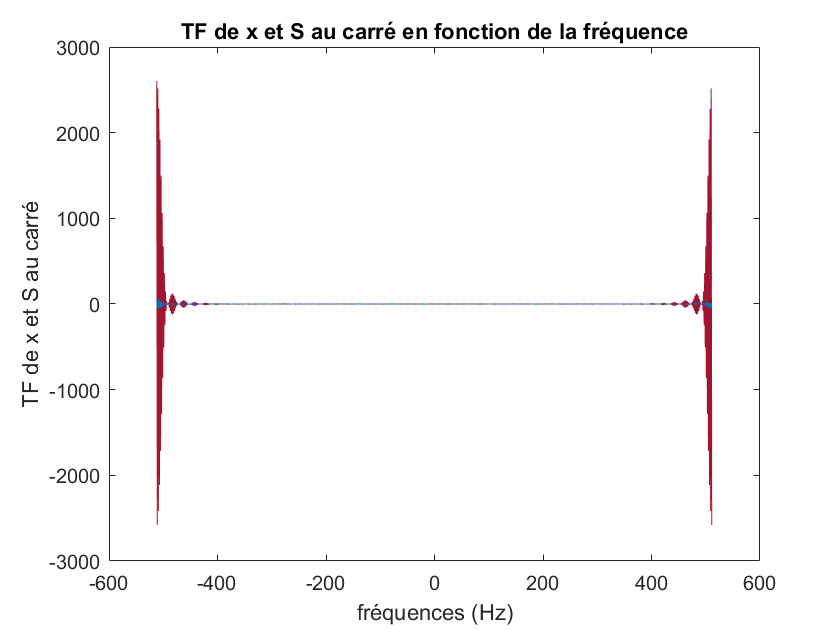

xlabel("fréquences (Hz)");
ylabel("Module de X et S");
title("TF de x et S au carré en fonction de la fréquence");

Partie 2

Partie 2.1

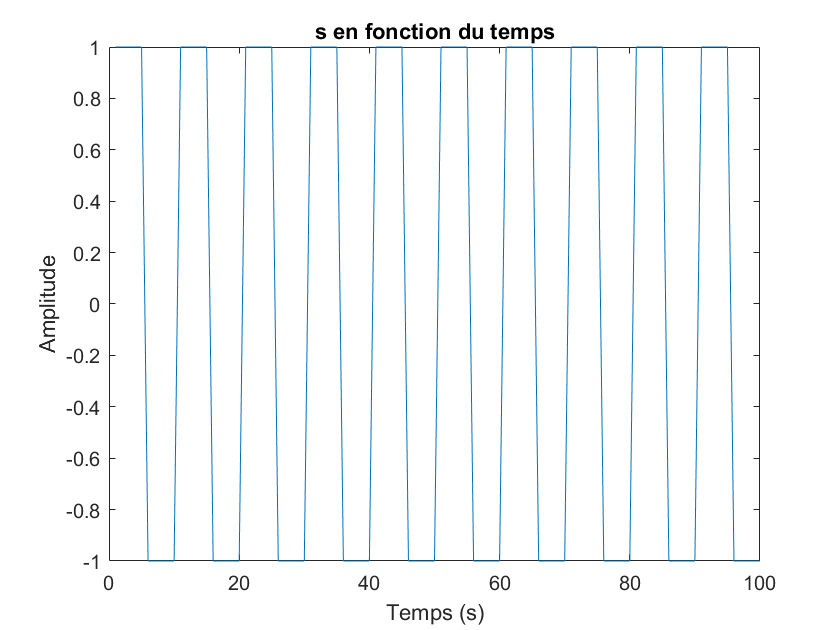

fe = 1000;                      % Fr�quence d'echantillonage en Hz
F = 100;                        % Fr�quence du signal en Hz
N = 10;                         % Nombre de p�riodes
D = N*(1/F);                % Duree du signal en s
t = 0 : 1/fe : D - (1 / fe);     % Creation de l'axe temporel
s = square(2 * pi * F * t);
figure(7);
plot(s);
xlabel("Temps (s)");
ylabel("Amplitude");
title("s en fonction du temps");

Partie 2.2

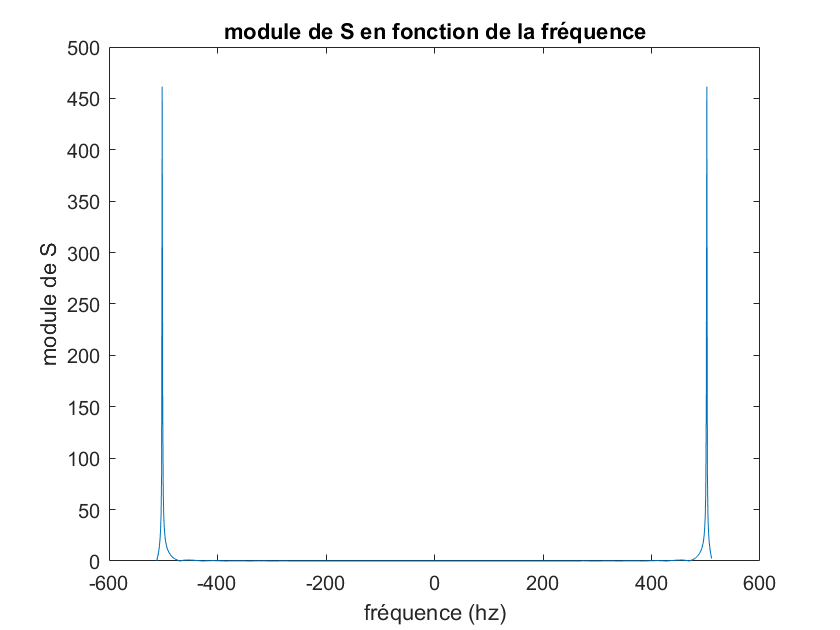

nb_points_fft = 1024;  % Nombre de points de la FFT
f = -nb_points_fft / 2 : 1 : nb_points_fft / 2 - 1;  % creation du vecteur frequentiel associe

S = fft(s, nb_points_fft);  % FFT de s
figure(8);
plot(f, abs(S));
xlabel("fréquence (hz)");
ylabel("module de S");
title("module de S en fonction de la fréquence");

Partie 3

% TF et TF inverse
% Initialisation
fe = 1000;                      % Frequence d'echantillonnage en Hz
F = 10;                         % Frequence du signal en Hz
D = 1;                          % Duree du signal en s
A = 3;                          % Amplitude du signal
t = 0 : 1 / fe : D - (1/fe);    % Creation de l'axe temporel

s = sin(2 * pi * F * t)

s =          0    0.0628    0.1253    0.1874    0.2487    0.3090    0.3681    0.4258    0.4818    0.5358    0.5878    0.6374    0.6845    0.7290    0.7705    0.8090    0.8443    0.8763    0.9048    0.9298    0.9511    0.9686    0.9823    0.9921    0.9980    1.0000    0.9980    0.9921    0.9823    0.9686    0.9511    0.9298    0.9048    0.8763    0.8443    0.8090    0.7705    0.7290    0.6845    0.6374    0.5878    0.5358    0.4818    0.4258    0.3681    0.3090    0.2487    0.1874    0.1253    0.0628


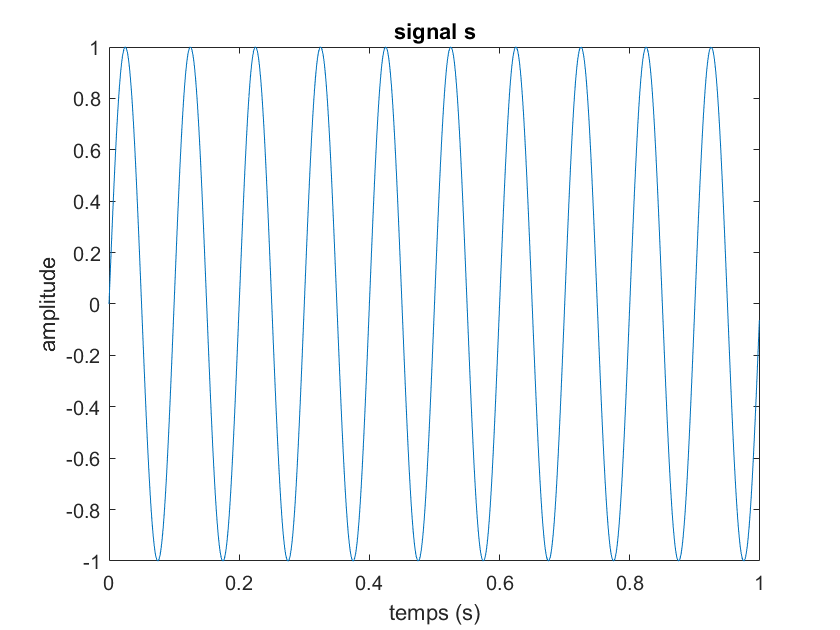

figure(9);
plot(t, s);
xlabel("temps (s)");
ylabel("amplitude");
title("signal s");

Partie 3.1

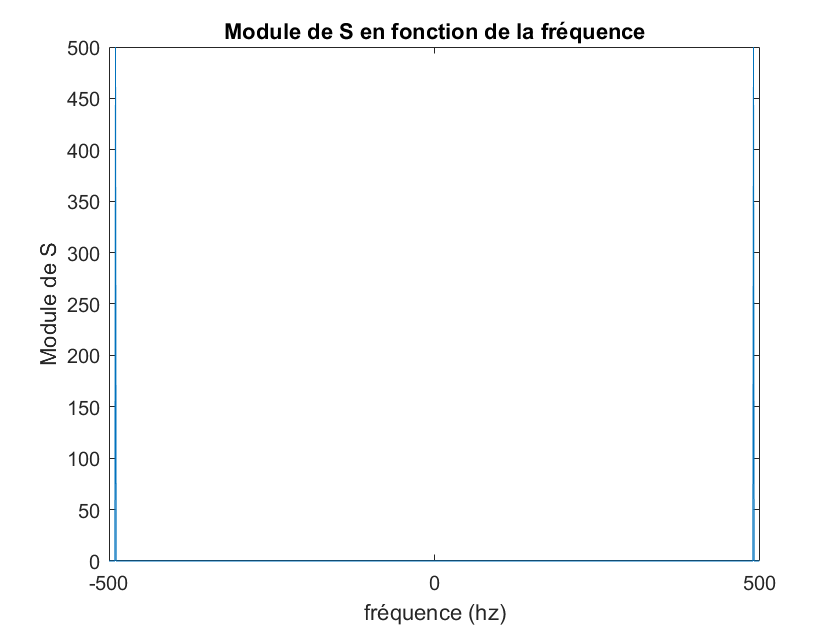

f = -fe / 2 : fe / length(s) : fe / 2 - fe / length(s); % Creation de l'axe des frequences
S = fft(s);  % FFT de s
figure(10);
plot(f, abs(S));
xlabel("fréquence (hz)");
ylabel("Module de S");
title("Module de S en fonction de la fréquence");

Partie 3.2

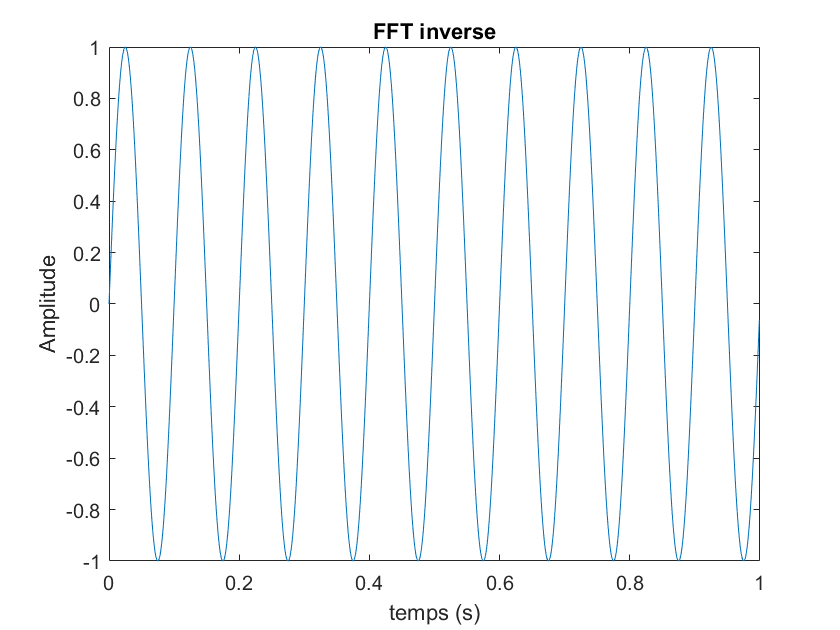

s = ifft(S);
figure(11);
plot(t, s);
xlabel("temps (s)");
ylabel("Amplitude");
title("FFT inverse");

Partie 3.3

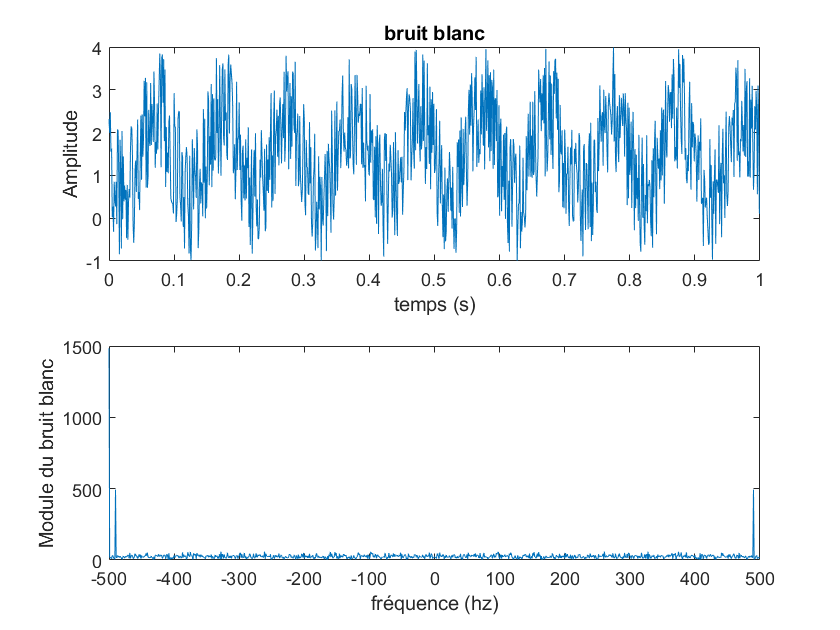

bruit = A * rand(1,length(s)) - s;  % Creation d'un bruit blanc centre d'ampitude 1
figure(12);
subplot(2, 1, 1); plot(t, bruit);
xlabel("temps (s)");
ylabel("Amplitude");
title("bruit blanc");
subplot(2, 1, 2); plot(f, abs(fft(bruit)));
xlabel("fréquence (hz)");
ylabel("Module du bruit blanc");

Partie 3.4

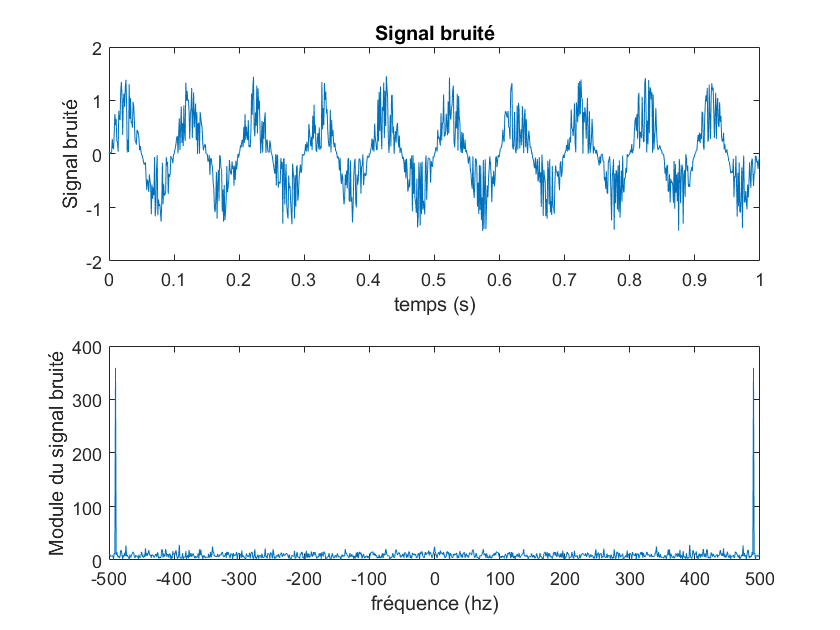

signal_bruite = s .* A / 2 .* rand(1, length(s));
SIGNAL_BRUITE = fft(signal_bruite);
figure(13);
subplot(2, 1, 1); plot(t, signal_bruite);
xlabel("temps (s)");
ylabel("Signal bruité");
title("Signal bruité");
subplot(2, 1, 2); plot(f, abs(SIGNAL_BRUITE));
xlabel("fréquence (hz)");
ylabel("Module du signal bruité");

Partie 3.5 et 3.6

M = ...;  % Amplitude maximale de la TF du signal bruite
seuil = ...;                 % Seuil � 10%
H = zeros(...);
for n = 1:...
   if ... > seuil*M
       H(n) = ...;
   end
end

SIGNAL_BRUITE_FILTRE = ...;
signal_bruite_filtre = ...;
figure(14); 
subplot(2, 1, ...); plot(..., ...);
xlabel(...);
ylabel(...);
title(...);
subplot(2, 1, ...); plot(..., ...);
xlabel(...);
ylabel(...);